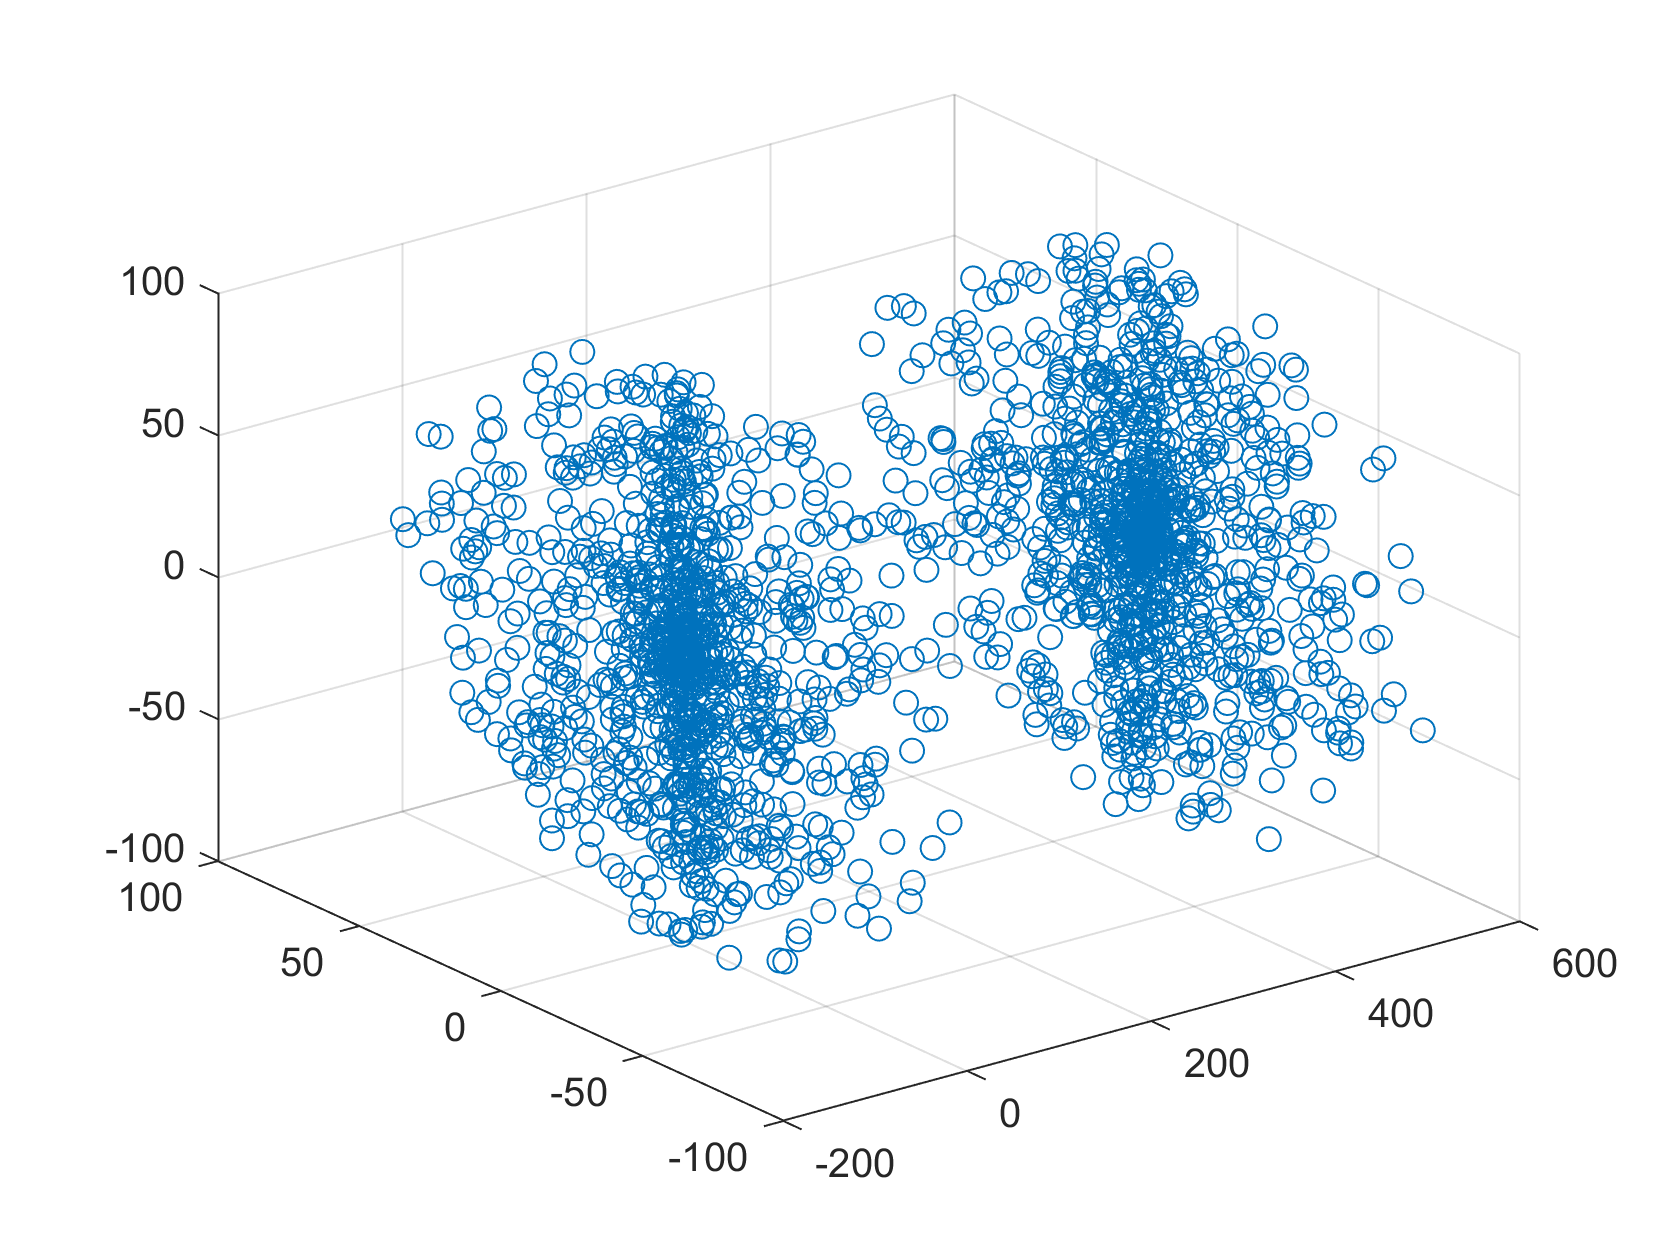

% Method Comparison 
% Comparing between Pairwise distribution, radial distribution, R50, and
% other algorithms for determining clustering
% Data generated is random 
n = 100;
k = 30;
cells = 500;
range = 100;
r50_list = zeros(k,n);
pw_list = zeros(k,n);
nn_list = zeros(k,n);
fn_list = zeros(k,n);

% points = genRandom(3, cells, range);
% xr = points(1,:);
% yr = points(2,:);
% zr = points(3,:);
% c = linspace(1, 10, length(x));
% s = 20;

R = 100;
numcells = 1000;
th = 2;
cr = 0.1;
ratios = zeros(n, 1);
[x1, y1, z1] = getUniform(R, numcells, 0, 0, 0);
[x2, y2, z2] = getUniform(R, numcells, R*5, 0, 0);
x = [x1, x2];
y = [y1, y2];
z = [z1, z2];
scatter3(x, y, z);

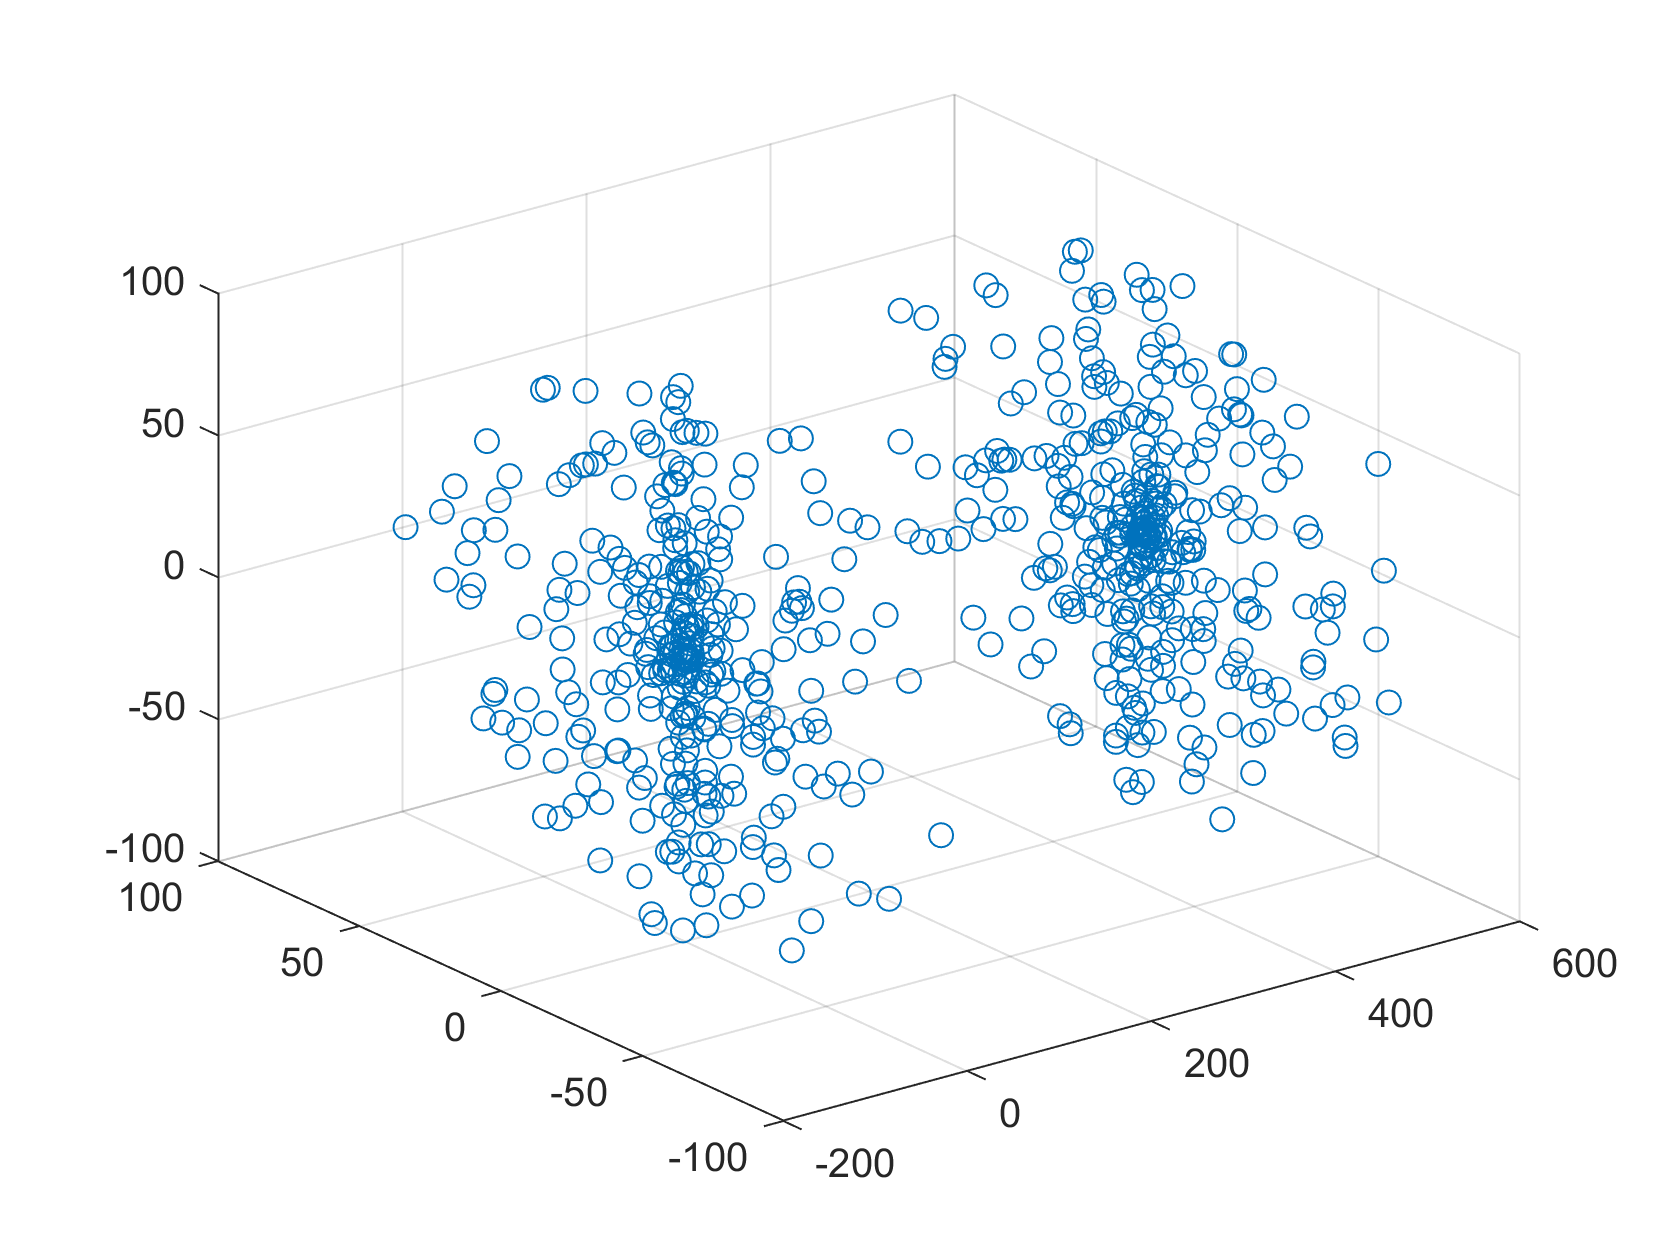

for i = 1:n
    r50 = getr50(x, y, z);
    pw = getPairwise(x, y, z);
    ratios(i) = r50 / pw;
    [x, y, z] = getWeightedThCluster(100, cr, x, y, z);
end
scatter3(x, y, z);

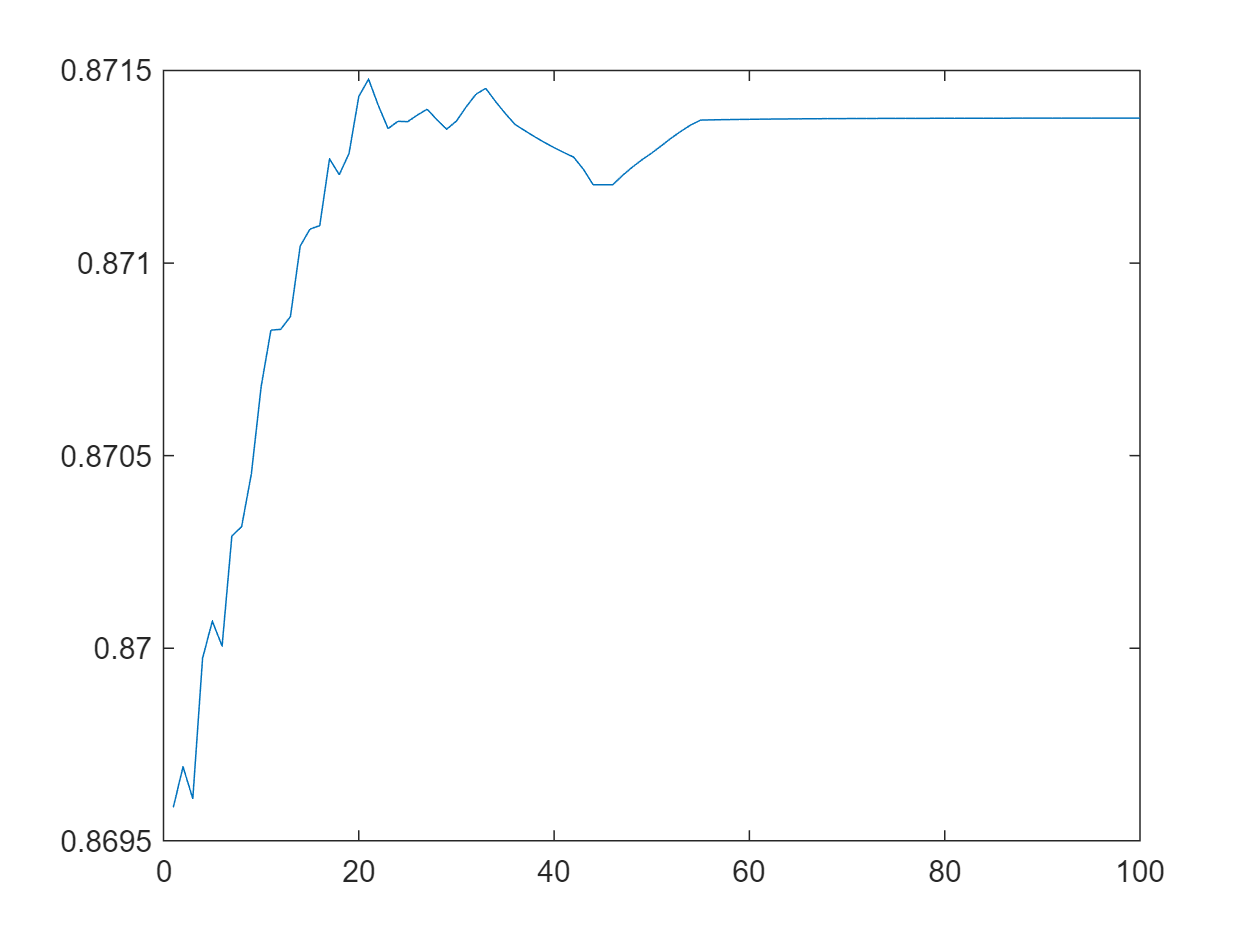

plot(ratios)











% [ids, c] = kmeans(points, 2);
% hold on
% scatter3(c(:, 1), c(:, 2), c(:, 3), 'rx', 'LineWidth', 5);
% x1 = points(ids==2, 1).';
% y1 = points(ids==2, 2).';
% z1 = points(ids==2, 3).';
% r50_clust1 = getr50(x1, y1, z1);
% pw_clust1 = getPairwise(x1, y1, z1);
% disp(pw_clust1);
% disp(r50_clust1);
% disp(r50_clust1/pw_clust1);

%  [xw, yw, zw] = getWeightedNNCluster(2, 0.25, x, y, z);
%  for i = 1:99
%     [xw, yw, zw] = getWeightedNNCluster(2, 0.25, xw, yw, zw);
%  end
% 
% [xn, yn, zn] = getNNCluster(2, 0.25, 0, x, y, z);
% for i = 1:99
%     [xn, yn, zn] = getNNCluster(2, 0.25, 0, xn, yn, zn);
% end
% 
% [xt, yt, zt] = getThCluster(100, 0.25, x, y, z);
% for i = 1:49
%     [xt, yt, zt] = getThCluster(100, 0.25, xt, yt, zt);
% end
% 
% [xwt, ywt, zwt] = getWeightedThCluster(100, 0.25, x, y, z);
% for i = 1:49
%     [xwt, ywt, zwt] = getWeightedThCluster(100, 0.25, xwt, ywt, zwt);
% end
% 
% scatter3(x, y, z, s, 'w');
% hold on
% % scatter3(xn, yn, zn, s, 'b');
% % hold on
% % scatter3(xw, yw, zw, s, 'k');
% % hold on
% scatter3(xwt, ywt, zwt, s, 'g', 'filled');
% hold on
% scatter3(xt, yt, zt, s, 'm');
% hold off
% legend('start', 'weighted threshold', 'threshold');


% for j = 1:k
%     points = genRandom(3, cells, range);
%     x = points(1,:);
%     y = points(2,:);
%     z = points(3,:);
%     for i = 1:n
%         r50_list(j, i) = getr50(x, y, z);
%         pw_list(j, i) = getPairwise(x, y, z);
%         nn_list(j, i) = getNearestN(x, y, z);
%         fn_list(j, i) = getFurthestN(x, y, z);
%     
%         [x, y, z] = getWeightedThCluster(50, 0.25, x, y, z);
%     end
%     if(0 == mod(j, 5))
%         disp(j);
%     end
% end
% boxplot(r50_list);
% title('R50');
% boxplot(pw_list);
% title('Pairwise');
% boxplot(nn_list);
% title('Nearest Neighbor');
% boxplot(fn_list);
% title('Furthest Neighbor');
% 
% 
% r50_mean = mean(r50_list);
% pw_mean = mean(pw_list);
% nn_mean = mean(nn_list);
% fn_mean = mean(fn_list);
% 
% plot(r50_mean);
% hold on
% plot(pw_mean);
% hold on
% plot(nn_mean);
% hold on
% plot(fn_mean);
% hold off
% legend('r50', 'pw', 'nn', 'fn');
% 
% r50_mean = r50_mean ./ max(r50_mean);
% pw_mean = pw_mean ./ max(pw_mean);
% nn_mean = nn_mean ./ max(nn_mean);
% fn_mean = fn_mean ./ max(fn_mean);
% 
% plot(r50_mean, 'b*');
% hold on
% plot(pw_mean, 'ro');
% hold on
% plot(nn_mean, 'm');
% hold on 
% plot(fn_mean, 'ko');
% hold off
% legend('r50', 'pw', 'nn', 'fn');
% disp('sum error r50 to pw');
% disp(sum(abs(r50_mean - pw_mean)));
% disp('sum error r50 to nn');
% disp(sum(abs(r50_mean - nn_mean)));
% disp('sum error pw to nn');
% disp(sum(abs(pw_mean - nn_mean)));
% scatter3(x,y,z);

function points = genRandom(dim, num, range)
    points = rand(dim, num).*range;
end

function [x,y,z] = getUniform(R, numcells, xoffset, yoffset, zoffset)
    points = zeros(numcells, 3);
    for i = 1:numcells
        r = rand(1, 1)*R;
        theta = rand(1,1)*2*pi;
        psi = rand(1,1)*pi;
        points(i, 1) = r * cos(theta) * sin(psi);
        points(i, 2) = r * sin(theta) * sin(psi);
        points(i, 3) = r * cos(psi);
    end
    points(:, 1) = points(:, 1) + xoffset;
    points(:, 2) = points(:, 2) + yoffset;
    points(:, 3) = points(:, 3) + zoffset;
    x = points(:, 1).';
    y = points(:, 2).';
    z = points(:, 3).';
end
% Clusters all points by: 
% 1 - finding the geometric center of a given cell with its 
% nn (number of nearest negighbors)
% 2 - brings it cr (cluster rate) closer to that center
% 3 - for all cells independant of one another (i.e. cell
% a could have cell b as a neighbor does not nessiscarly mean
% cell b has cell a as a neighbor. This is done to cluster the 
% entire population, similar to how I perdict is done in vitro
function [xn, yn, zn] = getNNCluster(nn, cr, distlim, x, y, z)
    xn = zeros(size(x));
    yn = zeros(size(y));
    zn = zeros(size(z));
    for i = 1:size(x, 2)
        [dist, indexes] = distToPoint(x(i), y(i), z(i), x, y, z);
        nnindex = indexes(1:nn);
        xcent = mean(x(nnindex));
        ycent = mean(y(nnindex));
        zcent = mean(z(nnindex));
        if(getDist(x(i), xcent, y(i), ycent, z(i), zcent) > distlim)
            xn(i) = (x(i)*(1-cr)) + (xcent*cr);
            yn(i) = (y(i)*cr) + (ycent*(1-cr));
            zn(i) = (z(i)*cr) + (zcent*(1-cr));
        else
            xn(i) = x(i);
            yn(i) = y(i);
            zn(i) = z(i);
        end
    end
end

% n Nearest neighbors using weighted center
function [xn, yn, zn] = getWeightedNNCluster(nn, cr, x, y, z)
    xn = zeros(size(x));
    yn = zeros(size(y));
    zn = zeros(size(z));
    for i = 1:size(x, 2)
        [dist, indexes] = distToPoint(x(i), y(i), z(i), x, y, z);
        xnear = x(indexes(1:nn));
        ynear = y(indexes(1:nn));
        znear = z(indexes(1:nn));
        distnear = dist(1:nn);
        distnearRecip = 1 ./ distnear;
        xmean = sum(xnear .* distnearRecip) * (1 / sum(distnearRecip));
        ymean = sum(ynear .* distnearRecip) * (1 / sum(distnearRecip));
        zmean = sum(znear .* distnearRecip) * (1 / sum(distnearRecip));
        xn(i) = ((1-cr)*x(i)) + (cr*xmean);
        yn(i) = ((1-cr)*y(i)) + (cr*ymean);
        zn(i) = ((1-cr)*z(i)) + (cr*zmean);
    end
end

% Threshold neighbor clustering
% Cluster only with points within a certain radius
% using unweighted geometric center
function [xn, yn, zn] = getThCluster(th, cr, x, y, z)
    xn = zeros(size(x));
    yn = zeros(size(y));
    zn = zeros(size(z));
    for i = 1:size(x, 2)
        [dist, indexes] = distToPoint(x(i), y(i), z(i), x, y, z);
        thdist = dist(dist < th);
        thindex = indexes(1:size(thdist));
        xcent = mean(x(thindex));
        ycent = mean(y(thindex));
        zcent = mean(z(thindex));
        xn(i) = (1-cr)*x(i) + cr*xcent;
        yn(i) = (1-cr)*y(i) + cr*ycent;
        zn(i) = (1-cr)*z(i) + cr*zcent;
    end
end

% Threshold neighbor clustering
% weighted center
function [xn, yn, zn] = getWeightedThCluster(th, cr, x, y, z)
    xn = zeros(size(x));
    yn = zeros(size(y));
    zn = zeros(size(z));
    for i = 1:size(x, 2)
        [dist, indexes] = distToPoint(x(i), y(i), z(i), x, y, z);
        thdist = dist(dist < th);
        thindex = indexes(1:size(thdist));
        thdistRecip = 1 ./ thdist;
        xth = x(thindex);
        yth = y(thindex);
        zth = z(thindex);
        xmean = sum(xth .* thdistRecip) * (1 / sum(thdistRecip));
        ymean = sum(yth .* thdistRecip) * (1 / sum(thdistRecip));
        zmean = sum(zth .* thdistRecip) * (1 / sum(thdistRecip));
        xn(i) = (1-cr)*x(i) + cr*xmean;
        yn(i) = (1-cr)*y(i) + cr*ymean;
        zn(i) = (1-cr)*z(i) + cr*zmean;
    end
end
% Returns the median distance of points from the geometeric center
function r50 = getr50(x, y, z)
    distances = centerDist(x,y,z);
    r50 = median(distances);
end

% Returns the mean distance of all points from each other
function pw = getPairwise(x, y, z)
    len = size(x, 2);
    distances = zeros(1, len*(len-1));
    for i = 1:len
        for j = 1:len
            if i ~= j
                distances(i*len + j) = getDist(x(i), x(j), y(i), y(j), z(i), z(j));
            end
        end
    end
    pw = mean(distances);
end

% Returns the mean nearest neighbor of all points
function nn = getNearestN(x, y, z)
    nns = zeros(size(x));
    for i = 1:size(x,2)
        curnn = 9999;
        for j = 1:size(x, 2)
            if i ~= j
                dist = getDist(x(i), x(j), y(i), y(j), z(i), z(j));
                if dist < curnn
                    curnn = dist;
                end
            end
        end
        nns(i) = curnn;
    end
    nn = mean(nns);
end

% Returns the mean farthest neighbor of all points
function fn = getFurthestN(x, y, z)
    fns = zeros(size(x));
    for i = 1:size(x, 2)
        currfn = 0;
        for j = 1:size(x, 2)
            if i ~= j
                dist = getDist(x(i), x(j), y(i), y(j), z(i), z(j));
                if dist > currfn
                    currfn = dist;
                end
            end
        end
        fns(i) = currfn;
    end
    fn = mean(fns);
end

% Returns distances from each points to the geometric center
function distances = centerDist(x,y,z)
    xmean = mean(x);
    ymean = mean(y);
    zmean = mean(z);
    distances = sort(sqrt(((xmean-x).^2) + ((ymean-y).^2) + ((zmean-z).^2)));
end

% Returns the distance between two points
function dist = getDist(x1, x2, y1, y2, z1, z2)
    dist = sqrt((x1-x2)^2 + (y1-y2)^2 + (z1-z2)^2);
end

% returns distances from each points to given point
function [distances, indexes] = distToPoint(x1, y1, z1, x, y, z)
    [distances, indexes] = sort(sqrt(((x1-x).^2) + ((y1-y).^2) + ((z1-z).^2)));
    % Remove distance 0
    if(distances(1) == 0)
        distances = distances(2:end);
        indexes = indexes(2:end);
    end
end

% Cartesian product of three sets
% pretty inefficeint but it gets the job done
function points = cartprod3(x, y, z)
    lx = size(x, 2);
    ly = size(y, 2);
    lz = size(z, 2);
    points = zeros(lx*ly*lz, 3);
    for i = 1:lx
        for j = 1:ly
            for k = 1:lz
                points((i-1)*ly*lz + (j-1)*lz + k, :) = ([x(i), y(j), z(k)]); 
            end
        end
    end
end